birdname = 'br177yw112';
syls = ['d'];
days = [62, 661,662, 73, 86, 88];

% set spectogram parameters
spect_params = struct();
spect_params.overlap_windowsize = [0.9 4];
spect_params.numWindows = 60;

% Initialize feature matrix
spects_all = [];
labels_all = [];
days_all = [];
failedSyls ={};

for d= 1:length(days)
    day = days(d)
    % change to folder containing files
    [~, ~,~,directory,~] = raster_params(birdname,day);
    cd(directory)

    spect_day = [];
    labels_day = [];

    try
    [spect_day, labels_day] = getSpectMatrix(syls, spect_params);
    [spects_all] = [spects_all; spect_day];
    [labels_all] = [labels_all, labels_day];
    [days_all] = [days_all; repmat(day,size(spect_day,1),1)];

    catch exception
        message = ['failed for: ' num2str(day) ' -syl ' syls];
        failedSyls = [failedSyls; message];
        disp(message)
    end

    cd ..

end

day = 62

day = 661

day = 662

day = 73

day = 86

day = 88

## Compile the matrix for feeding to tsne

% Step 3: Prepare Data for t-SNE
featureMatrix = spects_all;

% can implement something here that indexes just the rows for desired
% labels

% optional: normalize data?

% Step 4: Apply t-SNE with 3 dimensions
rng(42); % Set random seed for reproducibility
[tsneResult,loss] = tsne(featureMatrix, 'NumDimensions', 3, 'Distance','euclidean','Algorithm','exact');
disp(loss)

    0.8853



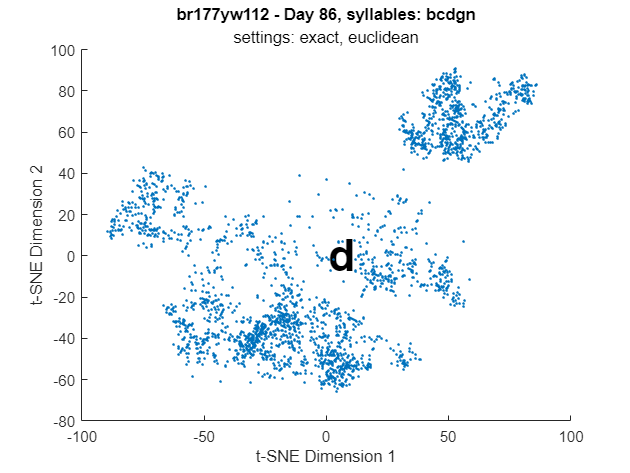

% Step 5: Assign unique colors based on labels
uniqueLabels = unique(labels_all);
numUniqueLabels = numel(uniqueLabels);
colors = lines(numUniqueLabels); % You can use any colormap you prefer

% Create a color map based on labels
labelColors = zeros(length(labels_all), 3);
for i = 1:numUniqueLabels
    labelColors(labels_all == uniqueLabels(i), :) = repmat(colors(i, :), [sum(labels_all == uniqueLabels(i)), 1]);
end

% Assuming your character labels are stored in a character array
charLabels = uniqueLabels; % Replace with your actual character labels

% Convert character labels to double
numericLabels = double(charLabels) - double('0') + 1;

% Create 3D scatter plot
figure;
hold on;
for i = 1:numUniqueLabels
    idx = labels_all == uniqueLabels(i);
    scatter3(tsneResult(idx, 1), tsneResult(idx, 2), tsneResult(idx, 3), 3, labelColors(idx, :), 'filled');
    
    % Label each cluster with the associated character
    centroid = mean(tsneResult(idx, :), 1);
    text(centroid(1), centroid(2), centroid(3), uniqueLabels(i), 'FontSize', 30, 'FontWeight', 'bold');
end
hold off;

title('br177yw112 - Day 86, syllables: bcdgn');
subtitle('settings: exact, euclidean')
xlabel('t-SNE1');
ylabel('t-SNE2');
zlabel('t-SNE3');